## Key Conceps about Images

### Image function

A mathematical function g(x,y) that represents the ligth intensity of each pixel of an image, which has finite values and a finite size.

where:

- x > 0 and y > 0

### Digital image

A function f(x,y) that assings the ligth intensity of each pixel of an image.

where:

- x and y are ints

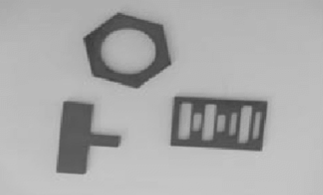   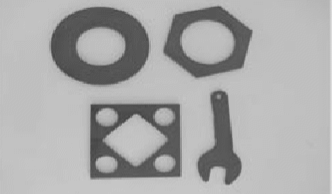   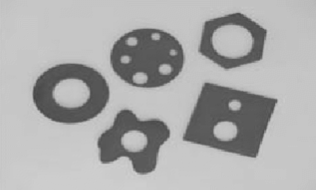

### Binary image

A function b(x,y) of an image f(x,y) which was quantized into two levels of lightning intensity, 0 and 1.

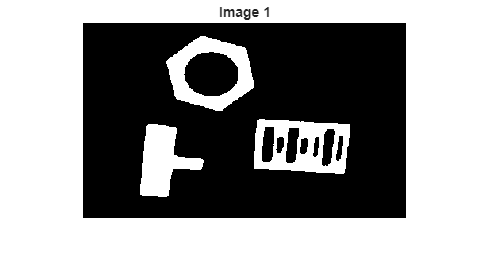

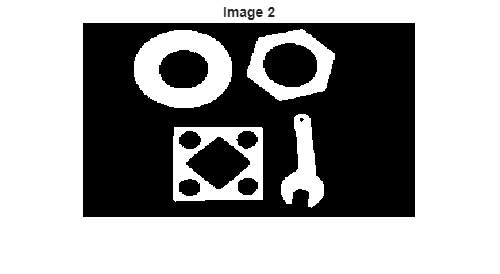

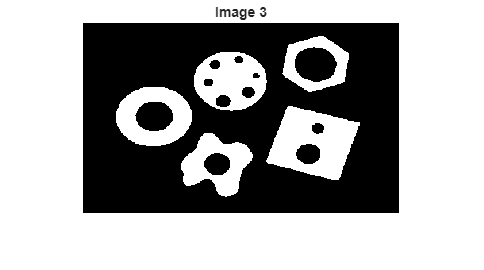

for p = 1:3
    img = sprintf('images\\Cap4 img%d.png', p);
    f = imread(img);
    [n, m, c] = size(f);
    niveles = [1 256];
    g = zeros(n, m);

    for y = 1:n
        for x = 1:m
            if f(y,x) <= 128
                g(y,x) = 1;
            else
                g(y,x) = 0;
            end
        end
    end
    figure;
    imshow(g);
    title(sprintf('Image %d', p));
end

### Image Histogram

An image histogram of a picture f(x,y) with l levels of light intensity, its a discrete function h(ri) given by:

Expression: h(ri) = ni / nT

where:

- ri: ligth intensity level

- ni: number of pixels with same light intensity

- nT: total number of pixels the image has

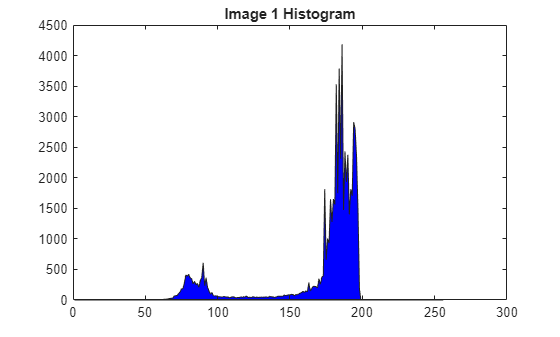

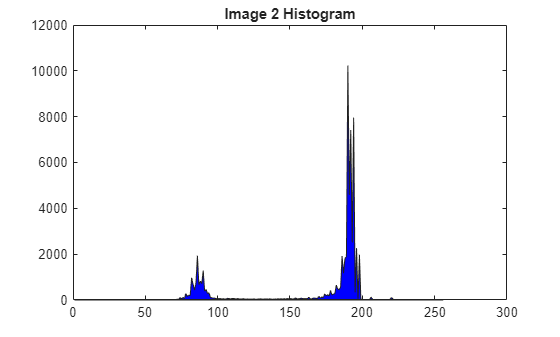

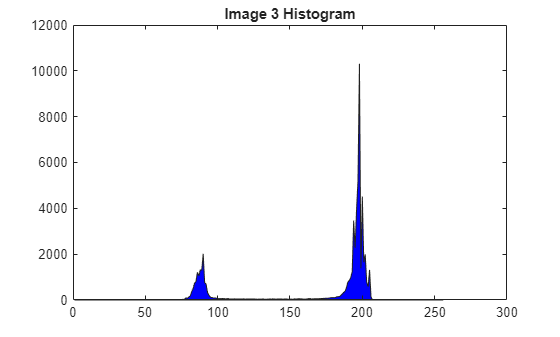

% images with 256 gray levels
for p = 1:3
    img = sprintf('images\\Cap4 img%d.png', p);
    f = imread(img);
    [n, m, a] = size(f);
    levels = 1:256;
    c = zeros(256,1);

    for y = 1:n
        for x = 1:m
            i = f(y,x);
            c(i) = c(i) + 1;
        end
    end
    figure;
    fill(levels, c, 'b');
    title(sprintf('Image %d Histogram', p));
end